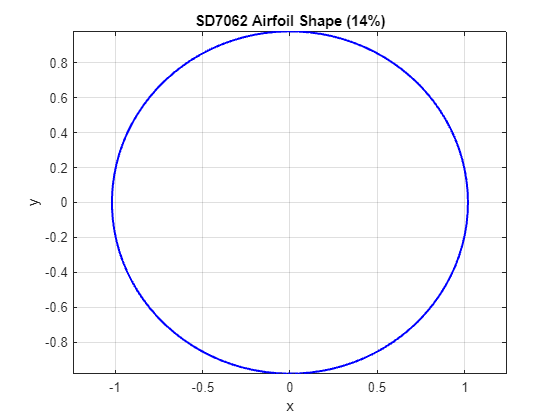

% Parameters for SD7062 airfoil
c = 0.14;  % Thickness-to-chord ratio
theta = linspace(0, 2*pi, 100);  % Angle parameterization

% Generate points on unit circle in z-plane
z_circle = exp(1i * theta);

% Apply Joukowsky transformation
w_airfoil = z_circle + c^2 ./ z_circle;

% Plotting
figure;
plot(real(w_airfoil), imag(w_airfoil), 'b', 'LineWidth', 1.5);
axis equal;
xlabel('x');
ylabel('y');
title('SD7062 Airfoil Shape (14%)');
grid on;